X = (-3:0.2:3)';
Y = sinc(X) + 0.1.*randn(length(X),1);

Xtrain = X(1:2:end);
Ytrain = Y(1:2:end);
Xtest = X(2:2:end);
Ytest = Y(2:2:end);


sig2 = 0.4;
gam = 10;
crit_L1 = bay_lssvm ({ Xtrain , Ytrain , 'f', gam , sig2 }, 1);
crit_L2 = bay_lssvm ({ Xtrain , Ytrain , 'f', gam , sig2 }, 2);
crit_L3 = bay_lssvm ({ Xtrain , Ytrain , 'f', gam , sig2 }, 3);

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


[~,alpha,b] = bay_optimize({Xtrain, Ytrain, 'f' , gam, sig2}, 1);

A =    -4.2660
    5.9658
    1.7562
   -3.5314
    1.0646
   -6.0488
   -2.5592
   10.3575
    0.9468
    2.1936


[~,gam] = bay_optimize({Xtrain, Ytrain, 'f' , gam, sig2}, 2);

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


[~,sig2] = bay_optimize ({Xtrain, Ytrain, 'f' , gam, sig2}, 3);

 
 

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
 

Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<

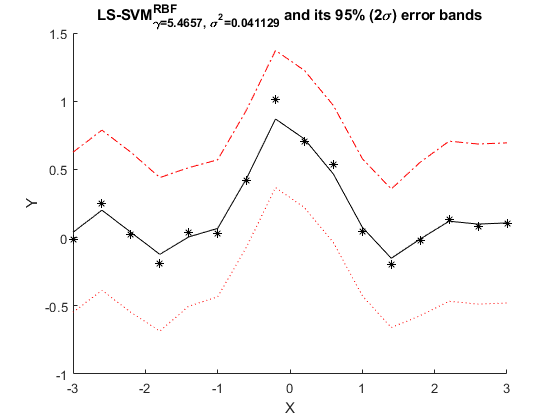

sig2e = bay_errorbar ({ Xtrain , Ytrain , 'function approximation', gam , sig2 }, 'figure');